# P03: Sistemas de inferencia difusos (FIS)

- **Chantaca De Jesus Uriel Eleazar**

- **Jimenez Esquivias Fernando Adrian.**

- **Moreno Velazquez Kattia Yamilet**

- **Rivera Picazo Angel**

- **Salazar Garcia Daniel**

## Objetivos

- Implementar sistemas de inferencia difusos, utilizando MATLAB

- Decodificar sistemas de inferencia difusos implementados en Simulink

## Introduccion

En el método Tsukamoto, cada consecuencia de las reglas IF-Then deben ser representado por un conjunto difuso con función de membresía monótona. En consecuencia, las salidas de interferencia de cada regla se presenta nítidamente de acuerdo con Predicado α (fuerza).

En el método Tsukamoto,  la operación de conjunto usado es una conjunción (Y), los valores de membresía antecedentes de la regla difusa [R1] es un parte del valor de membresía A1 de Var1 con el valor de pertenencia B1 de Var2. Según la teoría del conjunto operaciones, el valor de membresías anteriores de la operación de conjunción (Y) del difuso reglas [R1] es el valor mínimo entre el valor de membresía A1 de Var1 y el valor de pertenencia B1 de Var2. Asimismo, los valores de membresía de los antecedentes de las reglas difusas [R2] son el valor mínimo entre el valor de membresía A2 de Var1 y el valor de membresía B1 de Var2.

Al final se obtiene un resultado mediante un promedio ponderado, obteniendo que el método difuso tiene varias ventajas, como; tener el capacidad para resolver problemas complejos; representar conocimiento fácilmente interpretado por humanos; ser flexible para modelar la arquitectura y el mecanismo de inferencia que se puede adaptar a la problematica dada, otra razón está relacionada con la excelente precisión del método.

## **Problema 1**

 La herramienta **Fuzzy Logic Toolbox (FLT)**, Cuenta con una interfaz de gráfica de diseño de sistemas de inderencia difusos

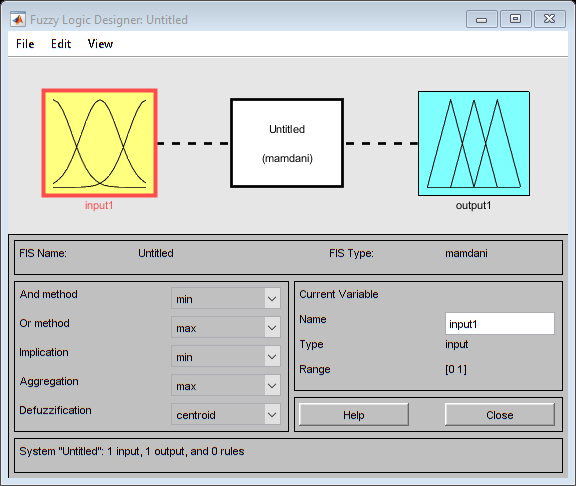

fuzzyLogicDesigner()

Para conecer el uso de esta interfaz se puede consultar la implentación del **problema de la propina **(problema de un sistema con dos entradas y una salida). La implementación es mediante la inferencia tipo Mandani. Para consultar dicha implementación puedes revisar el siguiente enlace: [Build Fuzzy Systems Using Fuzzy Logic Designer](https://www.mathworks.com/help/fuzzy/building-systems-with-fuzzy-logic-toolbox-software.html)

El problema  a desarrollar consistenen hacer uso de la herramienta gráfica para construir un sistema de inferencia difuso tipo Mandani. El problema es una variante del problema de la propina. Las condiciones son las siguientes

- 2 entradas (servicio y comida)

- El universo de discuros de ambas variables lingüisticas es $[0,100]$

- 1 salida (propina)

- El universo de discurso de esta variable lingúistica es [0,15] 

- Cada variable lingúistica dene tener por lo menos cuatro valores lingúisticos. Por lo menos un valor lingúistico debe ser una variación de un primitivo (por ejemplo: muy rica).

- La semantica de cada variable lingüista se deja a su *"experiencia como consumidor"*

- Se tienen que proponer por lo menos cuatro reglas si - entones, para la inferencia difusa (se tiene que utilizar por lo menos una vez cada conjunto difuso propuesto en su semántica)

En el desarollo se espera el planteamiento del problema a resolver, así como documentar la construcción correspondiente (parecido a lo presentado en el enlace anterior)

**¿Existe una situación donde el problema usual tenga "mal desempeño" al compararlo con tu implementación?**

SI, ya que el demo solo presenta 3 reglas para la inferencia difusa, la solucion que se implementa tiene todas las combinaciones de reglas para llevar acabo mejor la inferencia difusa.

**¿Existe una situación donde el problema usual tenga "mejor desempeño" al compararlo con tu implementación?**

Quizas habra alguna aplicacion donde se necesite menos mecanismos para una resolucion con menos reglas y datos con menos inferencias lo que permita tener menos variables y ser mas cerrado en cuanto a la informacion obtenida de entrada.

Problema1()

## Problema2

La impletación en Simulink de un FIS para aplicaciones de control,  se realiza principalmente con los siguientes bloques:

- [Fuzzy Logic Controller](https://www.mathworks.com/help/fuzzy/fuzzylogiccontroller.html) (FLC)

- [Fuzzy Logic Controller with Ruleviewer](https://www.mathworks.com/help/fuzzy/fuzzylogiccontrollerwithruleviewer.html) (FLCR)

El funcionamiento de los bloques sigue el principio de Simulink, se conectan las entradas, se procesan y se generan las salidas. En cada bloque basta indicar el nombre del sistema FIS. Este puede ser construido con el fuzzyLogicDesigner y exportado al workspace. También puede ser contruido mediante alguna de las posibles alternativas de código.

Exiten dos diferencias principales entre ambos bloques. El primero se puede asociar a  diferentes sistemas de inferencia, mientras el segundo, solo puede ser asociado a un FIS tipo Mandami o Sugeno, pero con la ayuda visual del RuleViewer (descrito en el enlace del problema 1). 

Para explorar  la implentación de los FIS en Simulink. Se trabajará con el control de nivel de agua en un tanque. 

Se tiene la siguiente implementación en Simulink

`open_system(``'sltank'``)`

La instrucción anterior abre el ejemplo antes mencionado. En particular se genera en el workspace la variable **tank** tipo *mamfis* (Sistema de inferencia difuso tipo Mamdani)

`tank`

`tank = `

`  mamfis with properties:`

`                       Name: "tank"`

`                  AndMethod: "prod"`

`                   OrMethod: "probor"`

`          ImplicationMethod: "prod"`

`          AggregationMethod: "max"`

`      DefuzzificationMethod: "centroid"`

`                     Inputs: [1×2 fisvar]`

`                    Outputs: [1×1 fisvar]`

`                      Rules: [1×5 fisrule]`

`    DisableStructuralChecks: 0`

`	See 'getTunableSettings' method for parameter optimization.`

Este FIS es el que se encuentra asociado al bloque FLC. Puedes explorar esta simulación de acuerdo a lo descrito en el siguiente enlace: [Water Level Control in a Tank](https://www.mathworks.com/help/fuzzy/water-level-control-in-a-tank.html). Puedes explorar el FIS de varias maneras, para hacerlo con la app 

`fuzzyLogicDesigner(tank)`

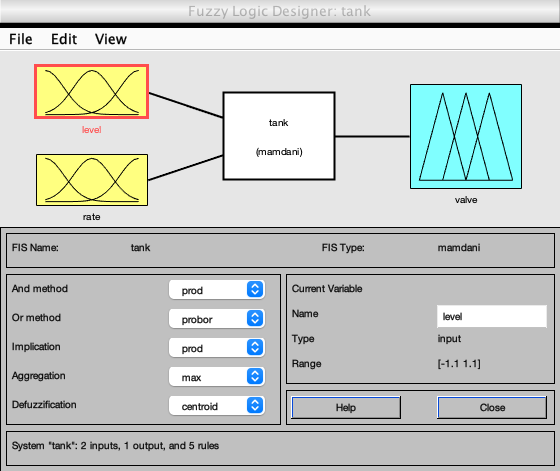

Con apoyo de lo anterior, contesta lo siguiente

**2.1** ¿Cuántas variables lingúistcas se tienen?

- level: Nivel del agua en el tanque

- rate: Indicador de cambio del nivel del agua

- valve: velocidad a la que se abre o se cierra la válvula de control.

**2.2** ¿Cuál es el universo de discurso de cada una?

- level:  [-1.1 1.1]

- rate:  [-0.35 0.35]

- valve:  [-1 1]

**2.3** Grafica las conjuntos difusos de cada variable lingüistica

- level

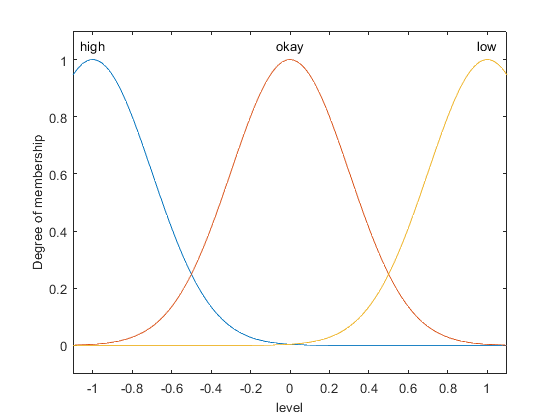

plotmf(tank,'input',1)

- rate

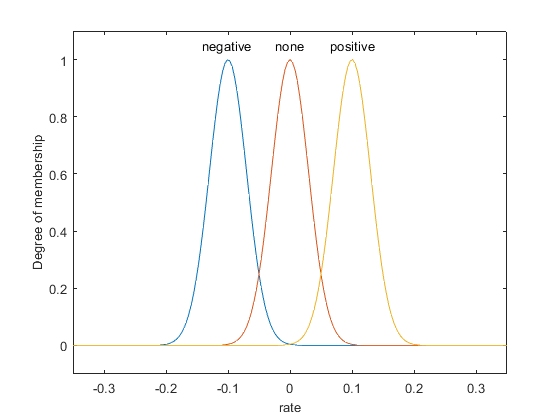

plotmf(tank,'input',2)

- valve

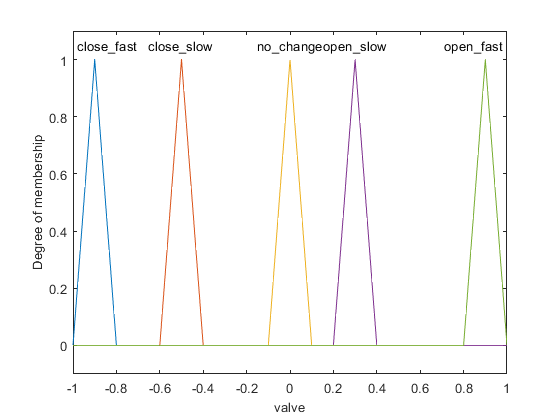

plotmf(tank,'output',1)

**2.4** Muestra las reglas de inferencia difusa utilizadas

tank.Rules

ans =   1×5 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                              Description                      
         ______________________________________________________

    1    "level==okay => valve=no_change (1)"                  
    2    "level==low => valve=open_fast (1)"                   
    3    "level==high => valve=close_fast (1)"                 
    4    "level==okay & rate==positive => valve=close_slow (1)"
    5    "level==okay & rate==negative => valve=open_slow (1)" 


**2.5** Explica en que consiste la implementación del sistema (una descripción general de todos bloques) en especial los bloque de visualización, así como la simulación mostrada

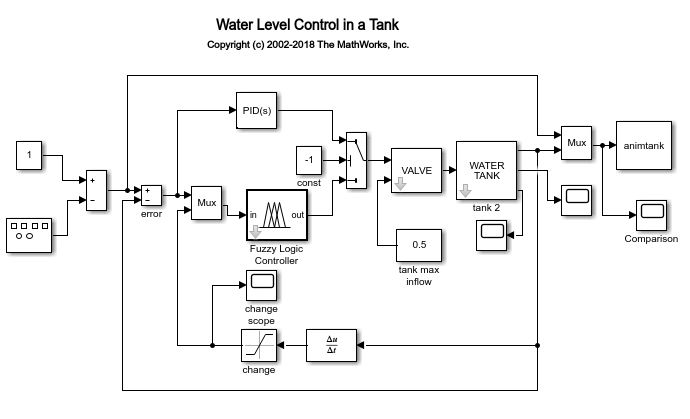

El sistema representa el llenado y vaciado de un tanque de agua a consecuencia de la implementación de las dos variables lingüísticas que se trabajaron (level y rate); el sistema comienza con una señal cuadrada de amplitud y periodo constantes y dada, y un valor unitario para ser sumadas evitando valores negativos.

Posteriormente está señal combinada es nuevamente sumada a la salida del sistema creando la retroalimentación de lazo cerrado que llamaremos error. Simultaneamente la salida del sistema es operada como derivada y gracias al bloque "change" la señal es limitada para ser ocupada, para ser multiplexada con el error.

Por otro lado, la misma salida de error es enviada a un bloque PID (proporcional integral y derivativo).

La salida multiplexada entra al Fuzzy Logic Controller, donde se operan las dos entradas para hacer todo el proceso Mamdani, donde se logra que las variables lingüísticas dejen su valor subjetivo para asignarles un valor numérico y una vez operadas la variable de salida tenga un valor numérico.

La salida del Fuzzy Logic Controller y la salida del PID entran en un bloque switch.

La señal obtenida hasta el momento es ingresada a dos subsistemas para ser operada en cada uno de ellos con el propósito de ser la señal final del sistema.  Dicha señal será nuevamente multiplexada con la señal original, para ser simulada.

## Problema 3

La logica difusa se puede implementar en varias aplicaciones en ingeniería, tal es el caso de:

Hela Lassoued, Raouf Ketata, Chapter 5 - Genetic fuzzy logic based system for arrhythmia classification, Editor(s): Olfa Boubaker, Control Theory in Biomedical Engineering, Academic Press, 2020, Pages 105-127, ISBN 9780128213506.

Contesta las siguentes preguntas respecto a la revisión del documento

**3.1** ¿Qué factores explican la presencia de arritmias?

Los factores que dan lugar a las arritmias son, la insalubridad, hábitos alimenticios, falta de actividad física, alto estrés, antecedentes familiares, edad y muchos otros.

**3.2** ¿A qué se refieren las siglas DSS?

Decision support system ó sistema de soporte de decisiones. En el caso de este articulo son empleados para la clasificación de arritmias.

**3.3** ¿A qué se refieren las siglas FLC?

Fuzzy logic controllers ó contraladores lodicos difusos. En el caso de este articulo son empleados para una retroalimentación.

**3.4 **¿A qué se refieren las siglas GA?

Genetic algorithms ó Algoritmos geneticos. En eñ caso de este articulo son empleados para definir las reglas y parametros que se daran para obtener un grado de pertenencia.

**3.5** ¿Cuál es el principal objetivo del capítulo 5?

Mejorar la precisión de la DSS basada en la clasificación de las arritmias cardíacas. 

**3.6 ** La base de datos  MIT-BIH Arrhythmia Database contine varios registros de distintos tipos de arritmias, ¿Cuáles son estos?   

Son cinco tipos de arritmias:

  Seno normal Ritmo (NSR)

  Contracción ventricular prematura (PVC)

  Izquierda Bloque de rama de paquete (LBBB)

  Bloque de rama de paquete derecho (RBBB)

  Ritmos marcados (P) 

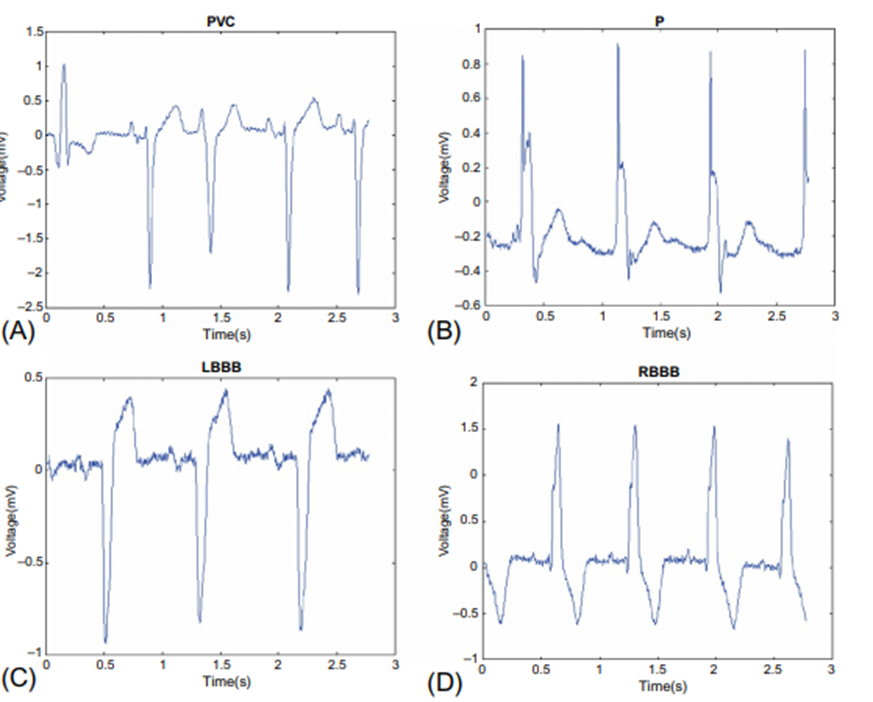

**3.7** ¿De que depende el desempeño de un  FLC?

Depende de las funciones de pertenencia y su base de reglas.

**3.8** ¿Para que utilizan un GA?

Para ajustar los parámetros de membrecía y el numero de reglas implementados en una FLC.

**3.9** La Figura 1 muestra un diagrama de bloques de la metodología implementada para la clasificación de arritmias. En nuestro caso nos interesa el bloque de clasificación. Este está compuesto por configuración y optimización. ¿En que consisten las entradas (input features) que recibe este bloque de clasificación? 

Son “características” que son las señales filtradas obtenidas del equipo de sensores (ECG).

**3.10** La principal ventaja de un FLC es que no es necesario un modelo matemático para la implementación del controlador (difuso). En general esto es el caso (como en el ejemplo del Problema 2), aunque puede suceder que para resolver cierta clase de problemas  sea necesario el modelo matemático de un subsistema. Se espera que la Figura 10 sea transparente en este momento. De acuerdo al texto ¿Cuál es la diferencia entre la inferencia de Mamdani y Sugeno?

Para Mamdani, mecanismo de inferencia, el antecedente y la consecuencia son ambos difusos variables. 

Para la inferencia de Sugeno, el antecedente es una variable difusa, pero la consecuencia es una función constante o lineal.

**3.11** De la sección 2.2.1 FLC configuration, ¿Cuántas variables lingüisticas se tienen? ¿Que tipo de conjuntos difusos son los consecuentes? ¿Cuantas reglas si-entones se proponen? ¿Que sistemas de inferencia se utiliza?   ¿Qué operaciones se utilizan para la Conjunción, Disyunción e Implicación?

6 variables lingüisticas con tres terminos lingüisticos por cada variable ,

singletons,

5 reglas,

Mamdani fuzzy inference,

conjuncion(AND) disyuncion(OR) implicacion(AND)

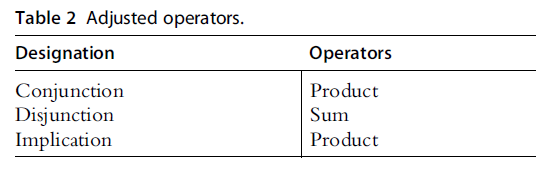

**3.12** Reporte el diagram de flujo del GA utilizado.

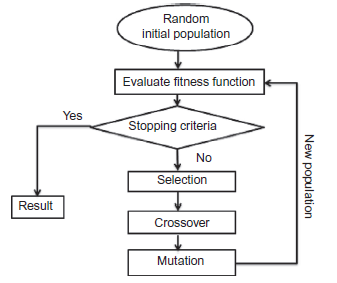

**3.13** Escriba la expresión matemática para la  *fitness function*  utilizada

**3.14** No se pretende profundizar sobre el funcionamiento del GA. Basta con tener una visión general de su uso en esta implementación, En particular los parametros a optimizar se les da el nombre de *cromosomas. *En este caso ¿Qué representan los cromosomas? ¿Cuáles son los resultados del proceso de optimización?

El cromosoma representa los parámetros gaussianos (μ y δ) y la cantidad de reglas difusas.

Los ajustes de distribucion de las funciones de membresia a relacion de las reglas difusas

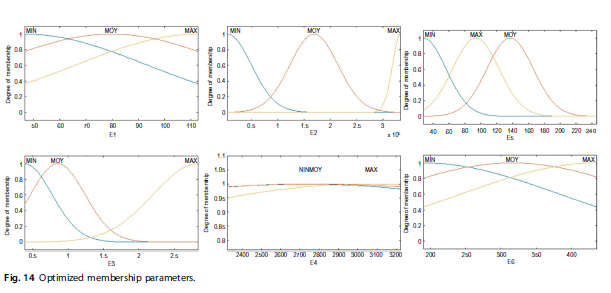

**3.15** ¿Cuáles fueron los resultados de la implementación?

Un mayor porcentaje de exactitud, sensibilidad y especifidad

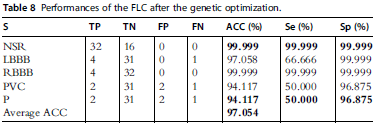

## Anexos

### Problema 1

[System]

Unrecognized function or variable 'System'.

Name='Problema1'
Type='mamdani'
Version=2.0
NumInputs=2
NumOutputs=1
NumRules=16
AndMethod='min'
OrMethod='max'
ImpMethod='min'
AggMethod='max'
DefuzzMethod='centroid'

[Input1]
Name='service'
Range=[0 100]
NumMFs=4
MF1='poor':'gaussmf',[15 0]
MF2='very_good':'gaussmf',[13.8502366172894 66.1]
MF3='excellent':'gaussmf',[15 100]
MF4='good':'gaussmf',[13.6 33.6126984126984]

[Input2]
Name='food'
Range=[0 100]
NumMFs=4
MF1='bad':'trapmf',[0 0 10 21.56]
MF2='very_good':'trapmf',[79 90 100 100]
MF3='normal':'trapmf',[22.1 28.9 38.9 49.3386243386243]
MF4='good':'trapmf',[49 58 68.3 79.8]

[Output1]
Name='tip'
Range=[0 15]
NumMFs=3
MF1='cheap':'trimf',[0 2.5 5]
MF2='average':'trimf',[5 7.5 10]
MF3='generous':'trimf',[10 12.5 15]


### Problema 2

[System]
Name='tank'
Type='mamdani'
Version=2.0
NumInputs=2
NumOutputs=1
NumRules=5
AndMethod='prod'
OrMethod='probor'
ImpMethod='prod'
AggMethod='max'
DefuzzMethod='centroid'

[Input1]
Name='level'
Range=[-1.1 1.1]
NumMFs=3
MF1='high':'gaussmf',[0.3 -1]
MF2='okay':'gaussmf',[0.3 0]
MF3='low':'gaussmf',[0.3 1]

[Input2]
Name='rate'
Range=[-0.35 0.35]
NumMFs=3
MF1='negative':'gaussmf',[0.03 -0.1]
MF2='none':'gaussmf',[0.03 0]
MF3='positive':'gaussmf',[0.03 0.1]

[Output1]
Name='valve'
Range=[-1 1]
NumMFs=5
MF1='close_fast':'trimf',[-1 -0.9 -0.8]
MF2='close_slow':'trimf',[-0.6 -0.5 -0.4]
MF3='no_change':'trimf',[-0.1 0 0.1]
MF4='open_slow':'trimf',[0.2 0.3 0.4]
MF5='open_fast':'trimf',[0.8 0.9 1]

[Rules]
2 0, 3 (1) : 1
3 0, 5 (1) : 1
1 0, 1 (1) : 1
2 3, 2 (1) : 1
2 1, 4 (1) : 1
